addpath(genpath('../helperFunctions'))

stimPath = '../stimulusSets/isettreeshrew/treeshrew_10/';
taskType = 'Camel_v2_test_nn';
stimSet = [taskType,'_quad/original/merged/'];

targ_idx = [0 6 9 13 17 32 38 40 44 55 60 65];

if strcmp(taskType,'Camel_Rhino_test_nn')
    distractor = 'rhino';
    dist_idx = [0 3 11 16 70 76 92];
else
    distractor = 'wrench';
    dist_idx = [0 14 26 83 87 92 93];
end

wave = 2:2:15;
orient = 0:15:165;
g = gabor(wave,orient);

allImgs = natsortfiles(dir([stimPath,stimSet]));
allImgs = allImgs(3:end);

%3 6 17 20

## Get Gabor filters for training set of targets and distractors

avgPwr_targ = nan(length(targ_idx),length(wave)*length(orient));
for tt = 1:length(targ_idx)
    img = double(imread(sprintf('%s%s/camel_%d.png',stimPath,stimSet,targ_idx(tt))));
    img = mean(img,3);

    outMag = imgaborfilt(img,g);
    avgPwr_targ(tt,:) = mean(outMag,[1,2]);
end

avgPwr_dist = nan(length(dist_idx),length(wave)*length(orient));
for dd = 1:length(dist_idx)
    img = double(imread(sprintf('%s%s/%s_%d.png',stimPath,stimSet,distractor,dist_idx(dd))));
    img = mean(img,3);

    outMag = imgaborfilt(img,g);
    avgPwr_dist(dd,:) = mean(outMag,[1,2]);
end

avgPwr_targ_norm = zscore(avgPwr_targ,[],1);
avgPwr_dist_norm = zscore(avgPwr_dist,[],1);

allDist = pdist2(avgPwr_targ_norm,avgPwr_dist_norm);
allDist2 = allDist';
allDist_flat = allDist2(:);
writematrix(allDist_flat,sprintf('./distData/%s/gabor_distances_norm2.csv',taskType))

## Train and test on Gabor data using SVM (train on 100-N images)

targ_idx_all = 0:100; targ_idx_all(targ_idx+1) = [];
dist_idx_all = 0:100; dist_idx_all(dist_idx+1) = [];

avgPwr_targ_all = nan(length(targ_idx_all),length(wave)*length(orient));
for tt = 1:length(targ_idx_all)
    img = double(imread(sprintf('%s%s/camel_%d.png',stimPath,stimSet,targ_idx_all(tt))));
    img = mean(img,3);

    outMag = imgaborfilt(img,g);
    avgPwr_targ_all(tt,:) = mean(outMag,[1,2]);
end

avgPwr_dist_all = nan(length(dist_idx_all),length(wave)*length(orient));
for dd = 1:length(dist_idx_all)
    img = double(imread(sprintf('%s%s/%s_%d.png',stimPath,stimSet,distractor,dist_idx_all(dd))));
    img = mean(img,3);

    outMag = imgaborfilt(img,g);
    avgPwr_dist_all(dd,:) = mean(outMag,[1,2]);
end

avgPwr_targ_all_norm = zscore(avgPwr_targ_all,[],1);
avgPwr_dist_all_norm = zscore(avgPwr_dist_all,[],1);


## Train SVM on additional images and test on experimental set

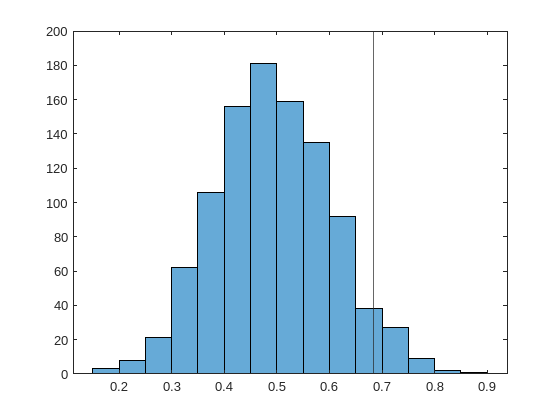

trainX_raw = [avgPwr_targ_all; avgPwr_dist_all];
testX_raw  = [avgPwr_targ;     avgPwr_dist];

mu = mean(trainX_raw);
sd = std(trainX_raw);
sd(sd == 0) = 1;

trainX = (trainX_raw - mu) ./ sd;
testX  = (testX_raw  - mu) ./ sd;

trainY = [zeros(length(targ_idx_all),1); ones(length(dist_idx_all),1)];
testY = [zeros(length(targ_idx),1); ones(length(dist_idx),1)];

Mdl = fitcsvm(trainX, trainY, 'Standardize',true);
pred_train = predict(Mdl,trainX);
pred = predict(Mdl, testX);
perf = sum((testY-pred)==0)/length(pred);

perf_samp = nan(1,1000);
for i = 1:1000
    y_shuf = trainY(randperm(length(trainY)));
    Mdl_shuf = fitcsvm(trainX, y_shuf);
    pred_shuf = predict(Mdl_shuf, testX);
    perf_samp(i) = sum((testY - pred_shuf) == 0) / length(testY);
end
p_val = mean(perf_samp >= perf);

figure;
histogram(perf_samp)
hold on;
xline(perf)